# Rad229 - Lecture 3:  Block Equation Matrix Simulations

## lec3_01.m:  Use plotm.m to Plot Magnetization

Here we give 2 examples to show the plotm.m function, which we hope is useful to you.  First, we just define 3 magnetization vectors and plot them.  Which color corresponds to which?  Second, we generate "dephased" magnetization - spins that have different phase angles.  

*Note that if you download and install arrow3D your plots will look nicer!  You can google "arrow3D matlab" or get it here:  https://www.mathworks.com/matlabcentral/fileexchange/71994-arrow-3d*

% Lecture 3, Example 01
% 
% Plot some mangetization vectors using plotm.m
%
% Simple 3x1 vectors - ; ends a row in Matlab:
M1 = [0; 0; 1];         % "Equilibrim" magnetization along Mz
M2 = [1; 0; 0];         % Magnetization long Mx
M3 = [0; 0.5; 0];       % Shorter magnetization along My

% plotm.m can plot a (3xN) array of spins all at once:
figure(1); disp('Example of 3 Spins');

Example of 3 Spins


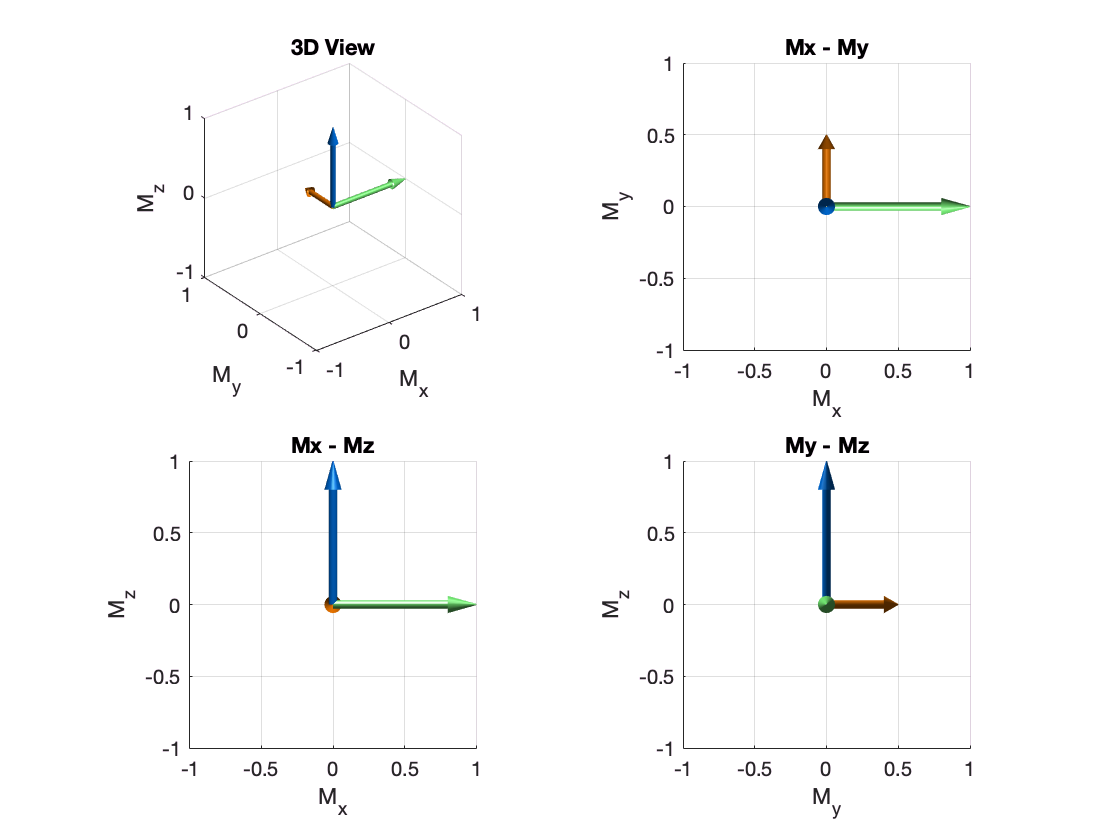

plotm([M1 M2 M3]);      % Notice we concatenate them horizontally.

%
% Which color corresponds to which M vector?
%
% You can also plot some dephased spins:
%pa
figure(2); disp('Dephased Spins');

Dephased Spins


x = [0:15];
M = [cos(2*pi*x/15); sin(2*pi*x/15); 0*x];
plotm(M);

Question 1:  What color corresponds to M1, M2 and M3?

Optional:  Have a look at plotm.m and the function it calls - showspins.m.

## lec3_02.m:  Animate Excitation and Precession

Here we will use the yrot.m and zrot.m functions to excite (nutate) and simulate precession.  

*Run this script from the command line - it does not work in the live output!*

% Lecture 3, Example 02
%
% Use the rotation functions to animate excitation, precession
%
M = [0;0;1];    % Equilibrium
Ne = 10;                % Frames - excitation
Np = 50;                % Frames - precession
Nrot = 1;               % cycles
Ry = yrot(-90/Ne);      % Rotation about My
Rz = zrot(360/Nrot/Np); % Rotation about Mz

figure(3); disp('Excitation/Rotation');

Excitation/Rotation


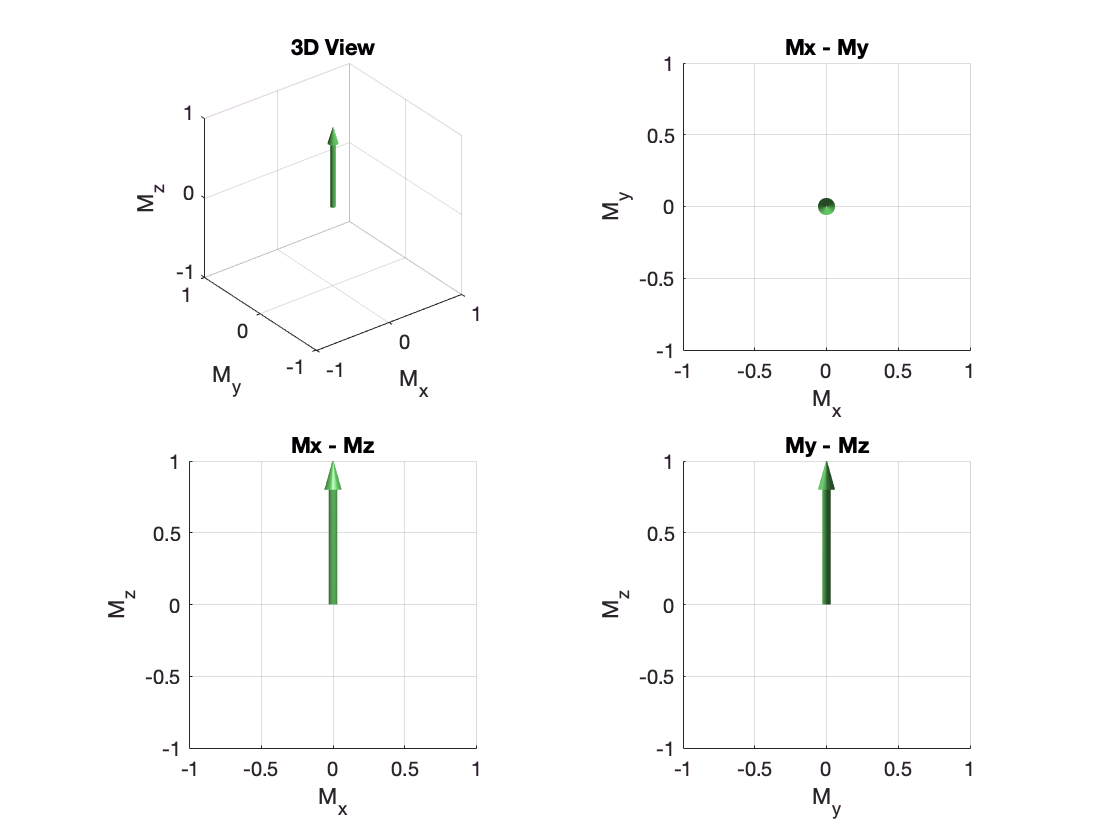

plotm(M);

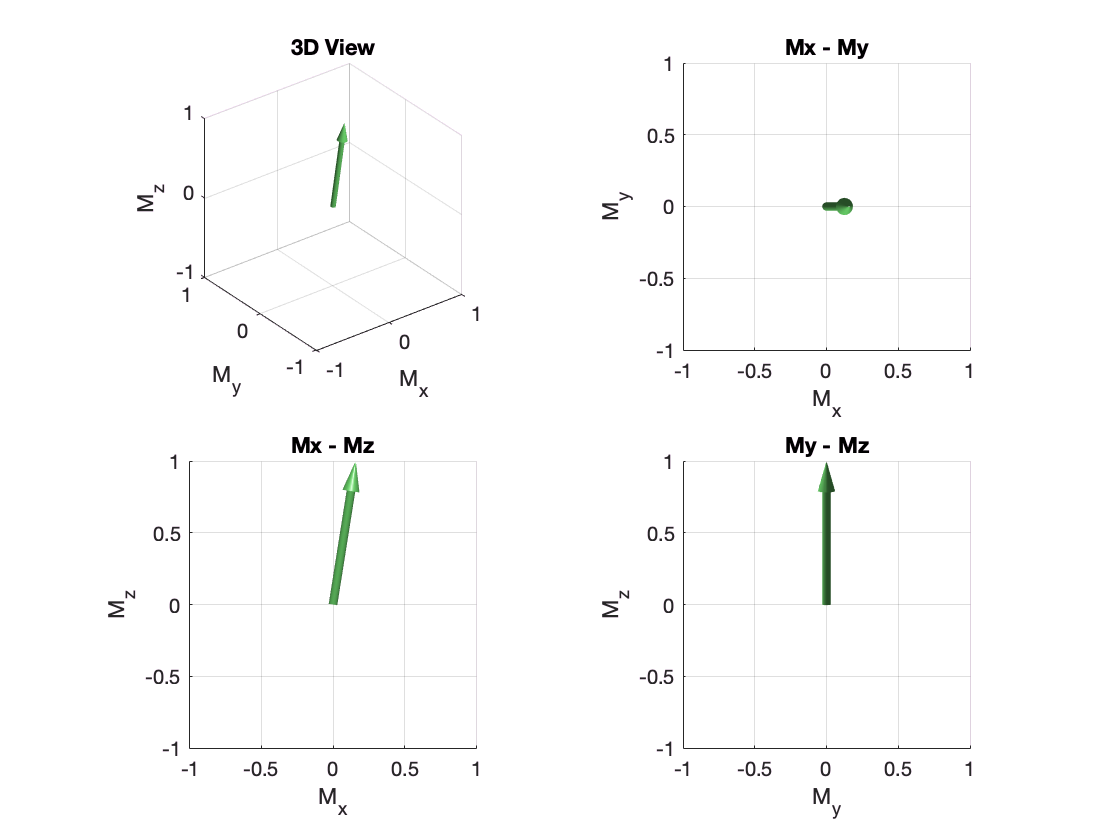

for n=1:Ne;
  M=Ry*M; plotm(M);     % Rotate and plot
  pause(0.1)
end;


for n=1:Np;
  M=Rz*M; plotm(M);     % Rotate and plot
  drawnow;
end;


Exercise 1:  Modify this code above to (1) increase the number of precession cycles to 5, possibly increasing the number of frames, and apply relaxation so that the magnetization returns to equilibrium, and transverse magnetization dies out in 3 rotations.

## lec3_03.m:  Simpler Animations

There is a general way we can animate rotations and relaxation, by splitting the overall A,B propagation into many frames.  Here we will demonstrate precession and relaxation, the solution to the prior exercise, but in a very compact form.

*Run this script from the command line!*

[A,B] = relax(5,2,1.5);      % Relaxation over 5sec with T1=2sec and T2=1.5sec.
M=abanim([1;0;0],40,A,B);    % Note we can't "split" a 360-degree (or more) rotation, due to ambiguity.


## lec3_04.m:  Phase Twist

This example simply shows a cycle of phase twist.  We will use this more later.  Notice that the "gradient" is applied very compactly, and could be successively applied in this manner quite efficiently.

% Lecture 3 - Example 4
% 
% Simulate/Plot a gradient of twist:

% -- Initialize
z = [-1:0.05:1];                % Z locations
M = [ones(size(z)); 0*z; 0*z];  % Excited magnetization.

% -- Phase Twist
ph = exp(pi*i*z);               % One cycle of phase.
phmult = [ph; conj(ph); 0*ph];  % 3xN phase Multiplier

% -- Apply and Plot
M = mc2mr(phmult.*mr2mc(M));    % Convert to Mx+i*My, add phase, convert back
disp('One cycle of Twist');

One cycle of Twist


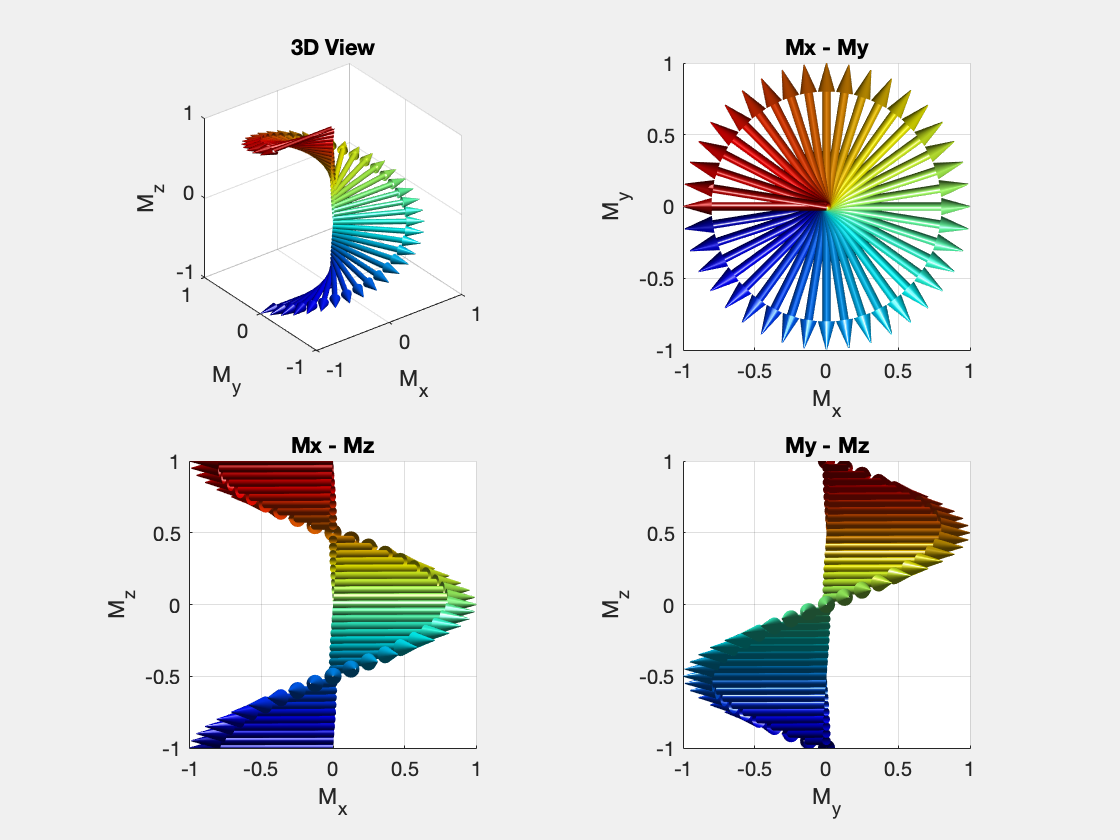

plotm(M,1,[0*z;0*z;z]);         % Plot twist!

## lec3_05.m:  Short-TR IR Signal Example

This is an example from the lecture, of using simple matrix operations to numerically calculate magnetization, for the IR sequence shown below:

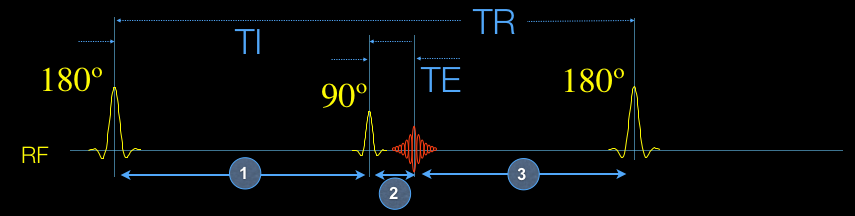

Here is the the Matlab code:

%       Short-TR IR Signal Example
%
%       (Use abprop to do this more compactly.)
%       Note we start applying A,B from TE onward as this is steady-state.

% Simple Inversion-Recovery sequence where TR is not long enough for
% full recovery so steady-state must be calculated.

%-- Times are all in seconds here.
TR=1;
TI = 0.5;
TE = 0.05;
T1 = 0.5;
T2 = 0.1;

%-- Shorthand - often describe E1 and E2 like this:

E1a = exp(-(TI/T1));
E2a = exp(-(TI/T2));
E1b = exp(-(TE/T1));
E2b = exp(-(TE/T2));
E1c = exp(-((TR-TI-TE)/T1));
E2c = exp(-((TR-TI-TE)/T2));

%-- Define A,B as in lecture example

A1 = diag([E2a E2a E1a]) * xrot(180);
B1 = [0;0;1-E1a];               
A2 = diag([E2b E2b E1b]) * xrot(90);
B2 = [0;0;1-E1b];
A3 = diag([E2c E2c E1c]);
B3 = [0;0;1-E1c];

%-- Could use abprop.m here

A = A2*A1*A3;                        
B = B2+A2*(B1+A1*B3);

Mss = inv(eye(3)-A)*B  

Mss =          0
    0.2424
    0.0952


## lec3_06.m:  Short-TR IR Signal Example (compact)

Here is the much more compact solution with abprop.m, where we do this in just one line (after initialization!):

% Lecture 3, Example 05
% 
%       Use abprop to do this compactly.
%       Note we start applying A,B from TE onward as this is steady-state.
%

% Simple Inversion-Recovery sequence where TR is not long enough for
% full recovery so steady-state must be calculated.

% Times are all in seconds here.
TR=1;
TI = 0.5;
TE = 0.05;
T1 = 0.5;
T2 = 0.1;

[A,B,Mss] = abprop(relax(TR-TE-TI,T1,T2,1),xrot(180), ...
        relax(TI,T1,T2,1),xrot(90), relax(TE,T1,T2,1));

Mss

Mss =          0
    0.2424
    0.0952


lec3_07.m:  RF Profile over Time

This example shows a simple simulation of an RF excitation pulse with a slice-selection and refocusing gradient.  Note that the core loop is very simple, though some initialization is required.  Rotations assume that the number of cycles induced over the slice is equal to the time x bandwidth product of the RF pulse.  The example also shows how you can make animated movies if you are interested, though this is turned off for the live view.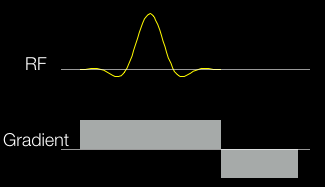

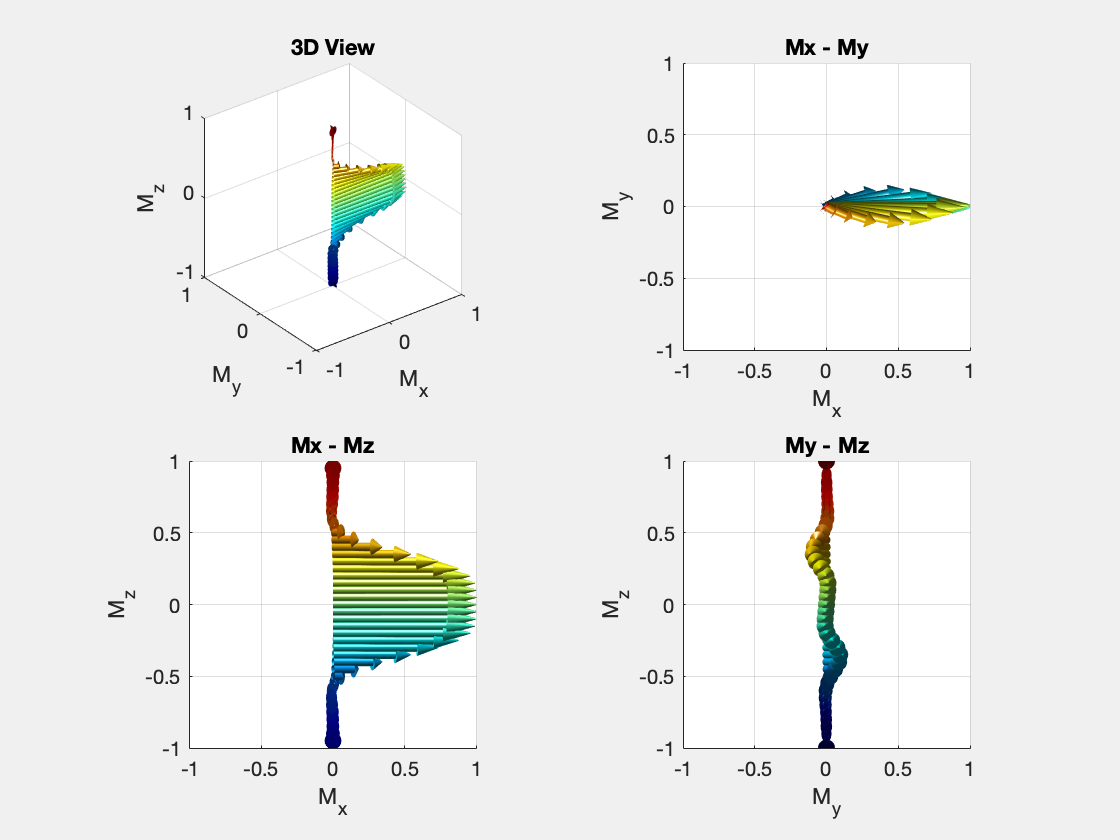

% Lecture 3 - Example 7
%
% Simulate/Plot an RF excitation

% -- Initialize
z = [-1:0.05:1];                % Z locations
M = [0*z; 0*z; ones(size(z))];  % Equilibrium magnetization.
anim = 0;                       % Set to 1 to "animate"
if (anim==1)
  global framenum;              % Setup to save frames
  global filestem;              
  framenum=0;
  filestem='/Users/brian/tmp/movie/im'  % Make image sequence
end;

Nrf = 100;                      % #points
TB = 4;                         % Time x Bandwidth product      
rf = msinc(Nrf,TB/2);
rf = rf*90/sum(rf);             % RF sums to 90 degrees.
% -- Phase Twist per point
ph = exp(pi*i*z*TB*3/Nrf);      % Time x Bandwidth cycles over slice,
                                % during RF duration, and show 3x slice
phmult = [ph; conj(ph); ones(size(ph))];  % 3xN phase Multiplier

T = [1 i 0;1 -i 0;0 0 1];       % Real to Complex M 
Txy = [1 0 0 ;0 1 0;0 0 0];     % extract Mxy for plots
Mc = mr2mc(M);                  % complex M vector

% -- Simulate RF excitation
for k=1:Nrf
  R = T*yrot(-rf(k))*inv(T);    % Rotation from RF
  Mc = phmult.*(R*Mc);          % Apply RF and gradient rotations.
  Mxy = Txy*real(mc2mr(Mc));    % Extract Mxy for plot
  if (anim==1)
    plotm(Mxy,1,[0*z;0*z;z]);   % Plot it.
    drawnow;
    saveframe;
  end;
end;

% -- Simulate gradient refocusing
for k=1:floor(Nrf/2)+4          % The "+4" is empirically determined!!
  Mc = conj(phmult).*Mc;        % Refocusing gradient rotation.
  Mxy = Txy*real(mc2mr(Mc));    % Extract Mxy for plot
  if (anim==1)
    plotm(Mxy,1,[0*z;0*z;z]);   % Plot it.
    drawnow;
    saveframe;
  end;
end;
   
% -- Final plot    
plotm(Mxy,1,[0*z;0*z;z]);       % Plot it.

drawnow;



## lec3_08.m  RF Excitation, Mx,My,Mz over time and space

This is a verbose example that shows a full loop with the hard-pulse approximation, for an excitation.  This can be repeated as in the lectures, with off-resoncance.

% Lecture 3 - Example 8
%
% Simulate RF pulse over different positions and time.
% This is quite a verbose example.
%
% -- Initialization
dt = .004;              % ms, sample spacing
tip = 90;               % desired tip.  
t = [-5:dt:5];          % extended time period to get 100 Hz spectral res.
tplot = find(abs(t)<=1); % only work on central 2 ms
rf=0*t;                 % allocate RF
rf(tplot) = msinc(length(tplot),3);     % put RF pulse in central part.
rf = rf/(sum(rf)*dt)*(tip/360)/42.58;   % scale for desired flip.

rfp = fftshift(fft(fftshift(rf)))*dt*42.58;             % RF profile, scaled
f = ([1:length(rfp)]-length(rfp)/2)/length(rfp)/dt;     % kHz

% -- Plot the RF and Frequency
figure(1);              % Plot the RF and profile.
subplot(2,1,1);
plot(t(tplot),rf(tplot)); xlabel('time(ms)'); ylabel('B1 (mT)');
subplot(2,1,2);
freqplot = find(abs(f)<5);                      % Plot only range of freqs.
plot(f(freqplot),abs(rfp(freqplot))*360);       
title('Small Tip Approximation'); ylabel('Flip (deg)'); xlabel('Freq (kHz)');
setprops;

% Bloch simulation

Gz = 2.5;       % mT/m  (gamma/2pi*Gz ~ 100 kHz/m, 1kHz/cm;
df = 0;         % kHz, off-resonance.

pos = [-.05:.0001:.05]; %       Positions to simulate

M = ones(3,length(tplot),length(pos));
M(1:2,:)=0;                             % M=[1;0;0];

% Note that we neglect relaxation during the RF.

for z = 1:length(pos)
  % Gradient rotation same for each interval
  Rgrad = zrot((42.58*pos(z)*Gz+df)*dt*360);    % zrot(a) = rotation matrix.
   
  for ti = 2:length(tplot)
    % Hard Pulse Approximation...
    alpha = rf(tplot(ti))*dt*42.58*360;         % RF rotation over interval
    Rrf = yrot(alpha);

    M(:,ti,z) = Rrf*Rgrad*M(:,ti-1,z);          % Apply RF, Gradient

  end;
end;

figure(2);
subplot(3,2,1);
plot(t(tplot),squeeze(M(1,:,ceil(length(pos)/2))));
xlabel('Time (ms)'); ylabel('M_x(t)');

subplot(3,2,3);
plot(t(tplot),squeeze(M(2,:,ceil(length(pos)/2))));
xlabel('Time (ms)'); ylabel('M_y(t)');

subplot(3,2,5);
plot(t(tplot),squeeze(M(3,:,ceil(length(pos)/2))));
xlabel('Time (ms)'); ylabel('M_z(t)');

subplot(3,2,2)
plot(pos*100,squeeze(M(1,end,:)),'b--'); hold on;
plot(pos*100,squeeze(M(2,end,:)),'r-'); hold off;
xlabel('Position (cm)'); ylabel('M_x(z) and M_y(z)');

subplot(3,2,4)
plot(pos*100,abs(squeeze(M(1,end,:)+i*M(2,end,:))));
xlabel('Position (cm)'); ylabel('M_{xy}(z)');

subplot(3,2,6)
plot(pos*100,squeeze(M(3,end,:)));
xlabel('Position (cm)'); ylabel('M_y(z)');

setprops;

